# Laboratorio 1

## Integrantes: Mateo Fernández (202320768), Gabriela Villalba (202411276) y Gabriel Sánchez (202420981)

clc;
clearvars;
close all;
format long g

carpetaActual = pwd;
versionMATLAB = version;
variablesIniciales = whos;

## Punto 1

**1.1**

d = [2 0 2 4 2 0 9 8 1]

d =      2     0     2     4     2     0     9     8     1



p = d(1,7)+2

p =     11


q = d(1,8)+3

q =     11


r = d(1,9)+4

r =      5


theta = 10*d(1,4)+d(1,5)

theta =     42


**1.2**

E1_grados = (sind(theta)+(cosd(p+q))^2+r^(-1))/(log10(p^2+q^2+10)+(log(r+20))/(sqrt(p^2+q^2+r^2)))

E1_grados =          0.665334616880019


E2_grados = ((p+q)^2/(tand(theta+5)))*log(r+1)+power(((p+r)*exp(-q/10))/log2(p*q+r+2),1/3)

E2_grados =           809.600804013371



E1_radianes = (sin(theta)+(cosd(p+q))^2+r^(-1))/(log10(p^2+q^2+10)+(log(r+20))/(sqrt(p^2+q^2+r^2)))

E1_radianes =         0.0550911188098749


E2_radianes = ((p+q)^2/(tan(theta+5)))*log(r+1)+power(((p+r)*exp(-q/10))/log2(p*q+r+2),1/3)

E2_radianes =           -6963.0999176656


**Explique el efecto de interpretar θ con una unidad angular diferente:**

El hecho de utilizar $sind$ vs $sin
$ puede tener implicaciones significativas dentro del calculo. La función seno no es lineal y un cambio ligero en el calculo de este puede tener implicaciones significativas, por ejemplo, el angulo de 45º es $\frac{1}{8}$de circulo por lo que el seno de 45º es $\frac{\sqrt{2}}{2}$, sin embargo 45 radianes es el equivalente de aproximadamente 7.16 vueltas al circulo unitario, lo que es aproximadamente 57º. Por lo que comprender bajo que escala se mide el angulo es importante para prevenir inconsistencias numericas.

**1.3**

T = table(p', q', r', theta', E1_grados', E2_grados', E1_radianes', E2_radianes', ...
    'VariableNames', {'p', 'q', 'r', 'theta', 'E1_grados', 'E2_grados', 'E1_radianes', 'E2_radianes'})

T = 1×8 table
    p     q     r    theta        E1_grados           E2_grados           E1_radianes          E2_radianes   
    __    __    _    _____    _________________    ________________    __________________    ________________

    11    11    5     42      0.665334616880019    809.600804013371    0.0550911188098749    -6963.0999176656


format short
E1_grados

E1_grados = 0.6653

El formato short se encarga de mostrar numeros con maximo 4 cifras decimales, es estético y solo afecta lo que muestra la consola, internamente los numeros se manejan como doubles y son los tipos de datos numericos estandar del programa. Estos proveen alrededor de 15-17 cifras decimales de precisión. Matlab al ser un lenguaje de programación con tipado dinamico (asigna el tipo de variable de forma dinamica) no se tiene que especificar el tipo de dato a ingresar, sin embargo si se requiere o se prefiere algún tipo de dato en especifico siempre se pueden convertir los datos double a single o a enteros o algun dato de preferencia.

format long;
class(E1_grados)

ans = 'double'

E1_grados

E1_grados =    0.665334616880019


Por el contrario el formato long se encarga de mostrar resultados con hasta 15 cifras decimales

fprintf("%4.6f", E1_grados)

0.665335

fprintf("%2.8f", E1_grados)

0.66533462

En el formato fprintf permite escribir datos a un archivo de texto o imprimir directamente a la consola si se omite la ruta al archivo de texto a editar. De manera similar al lenguaje de programacion C, se utilizan ciertos operadores dentro de un string, en este caso el % indica "reemplazar por cierta variable" e inmediatamente después se especifica el tipo de variable y/o el formato con el que se muestra. Como se está manejando un numero (tipo float) se especifican la cantidad de numeros enteros a mostrar y la cantidad de decimales fijos a mostrar. Si se quiere mostrar un entero se utilizaría %d, o si se quisiese en notación cientifica se utilizaria %e, o una cadena de caracteres sería %s.

log(0)

ans =   -Inf


sqrt(-1)

ans =   0.000000000000000 + 1.000000000000000i


A pesar de que ciertas funciones tienen restricciones en su dominio como los logaritmos o las raices, Matlab puede llegar a manejar de forma completa algunas de estas funciones. Por ejemplo calcular el logaritmo natural de 0 resulta en -Inf, pero no en error y la raiz cuadrada de -1 resulta en 1i y no en error, por lo que a pesar de que pueden dar valores poco utiles, no afecta en la compilacion del programa.

## Punto 2

**2.1**

**Función auxiliar reporte de información de los arreglos**

function info_arreglo(nombre_arreglo, arreglo)

    tamano = size(arreglo);
    num_filas = tamano(1);
    num_columnas = tamano(2);
    cantidad_elementos = numel(arreglo); 
    tipo_dato = class(arreglo); 
    valor_min = min(arreglo(:));  
    valor_max = max(arreglo(:)); 
    memoria = whos('arreglo');
    memoria_ocupada = memoria.bytes;

    fprintf('%s\n', nombre_arreglo);
    fprintf('Tamaño: %d filas x %d columnas\n', num_filas, num_columnas);
    fprintf('# de elementos: %d\n', cantidad_elementos);
    fprintf('Clase: %s\n', tipo_dato);
    fprintf('Mínimo: %g | Máximo: %g\n', valor_min, valor_max);
    fprintf('Memoria ocupada: %d bytes\n\n', memoria_ocupada);
end

A = [p q r; q+r p+1 q-1; r-p q+2 p+r]

A =     11    11     5
    16    12    10
    -6    13    16


B = [r+1 p-1 q; p+q r 1; q-r p+2 r+2]

B =      6    10    11
    22     5     1
     6    13     7



vector_fila = [p q r p+r];              
vector_columna = [p; q; r; p+r];           
matriz_diagonal = diag([p q r]);            
matriz_toep = toeplitz([p q r]);

info_arreglo('Vector fila', vector_fila);

Vector fila
Tamaño: 1 filas x 4 columnas
# de elementos: 4
Clase: double
Mínimo: 5 | Máximo: 16
Memoria ocupada: 32 bytes



info_arreglo('Vector columna', vector_columna);

Vector columna
Tamaño: 4 filas x 1 columnas
# de elementos: 4
Clase: double
Mínimo: 5 | Máximo: 16
Memoria ocupada: 32 bytes



info_arreglo('Matriz diagonal', matriz_diagonal);

Matriz diagonal
Tamaño: 3 filas x 3 columnas
# de elementos: 9
Clase: double
Mínimo: 0 | Máximo: 11
Memoria ocupada: 72 bytes



info_arreglo('Matriz de Toeplitz', matriz_toep);

Matriz de Toeplitz
Tamaño: 3 filas x 3 columnas
# de elementos: 9
Clase: double
Mínimo: 5 | Máximo: 11
Memoria ocupada: 72 bytes



**2.2**

suma = A + B

suma =     17    21    16
    38    17    11
     0    26    23


El Significado Matematico de A + B es simplemente la suma individual de cada uno de los indices correspondientes, es decir el indice a11 se suma con b11 y el indice a12 se suma con b12 y asi sucesivamente.

producto_AB = A*B

producto_AB =    338   230   167
   420   350   258
   346   213    59


Al utilizarse la multiplicación entre matrices, se define que el resultado entre la multiplicación de matrices tendra una dimesión a*c cuanto las matrices de entrada tienen dimensión (a,b*b,c), note que si la dimension del "ancho" de la primera matriz no coincide con la dimension del "alto" de la segunda matriz la multiplicación matricial NO está definida. La multiplicación matricial NO es conmutativa debido al algoritmo que se utiliza para calcularla (fila*columna) en donde al cambio en el orden de los indices afecta el resultado de la multiplicación fila*columna. Para verificar, se calcula el resultado c11 (el primer indice de ans, que en este caso es 338).

A(1,:)*B(:,1)

ans =    338


Se accede a la primera fila de la matriz A utilizando slicing, es decir se accede a la primera fila y se guardan TODOS los valores de esa columna con el operador :

De manera similar, se accede la primera columna de la matriz B utilizando solamente la primera columna, pero se almacenan TODAS las filas. Como el resultado de ambas operaciones da un vector, se pueden multiplicar directamente para obtener el producto punto entre estos dos vectores que da el mismo resultado que se obtuvo multiplicando las matrices completas de A y de B.

producto_BA = B*A

producto_BA =    160   329   306
   316   315   176
   232   313   272


prod_Elemento = A.*B

prod_Elemento =     66   110    55
   352    60    10
   -36   169   112


El producto de A .* B es equivalente a la multiplicación individual entre los indices de las matrices, es decir de manera similar a A+B, se obtiene que a11*b11 es igual al primer indice del resultado. De manera similar, el segundo indice resultante es a12*b12 y asi sucesivamente.

div_Elemento = A./B

div_Elemento =    1.833333333333333   1.100000000000000   0.454545454545455
   0.727272727272727   2.400000000000000  10.000000000000000
  -1.000000000000000   1.000000000000000   2.285714285714286


verificacion_AB_21= A(2,1)*B(1,1) + A(2,2)*B(2,1) + A(2,3)*B(3,1);
fprintf('Verificación manual AB(2,1) = %g | MATLAB AB(2,1) = %g\n', verificacion_AB_21, producto_AB(2,1));

Verificación manual AB(2,1) = 420 | MATLAB AB(2,1) = 420


**2.3**

C = [4 2 7; 3 5 9];
try
    incompatible = A*C;
catch Mensaje_error
    fprintf('Mensaje de MATLAB:\n%s\n\n', Mensaje_error.message);
    fprintf('Dimensiones A: %dx%d | Dimensiones C: %dx%d\n', size(A,1), size(A,2), size(C,1), size(C,2));
end

Mensaje de MATLAB:
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.



Dimensiones A: 3x3 | Dimensiones C: 2x3



correccion_1 = C*A

correccion_1 =     34   159   152
    59   210   209


disp('C*A ='); disp(correccion_1)

C*A =
    34   159   152
    59   210   209



fprintf('Corrección 1 C*A:| Dimensiones = %dx%d\n',size(correccion_1,1), size(correccion_1,2));

Corrección 1 C*A:| Dimensiones = 2x3


C_tranpuesta = C'; 
correccion_2 = A*C_tranpuesta;
disp('A*C'' ='); disp(correccion_2)

A*C' =
   101   133
   158   198
   114   191



fprintf('Corrección 2 A*C''| Dimensiones = %dx%d\n',size(correccion_2,1), size(correccion_2,2));

Corrección 2 A*C'| Dimensiones = 3x2


Al Intentar multiplicar la Matriz A1 de dimensiones (2x3) y la matriz B1 de dimensiones (2x3) la multiplicacion falla debido a que no se siguen las reglas de dimensionamiento previamente explicadas en donde se debe cumplir (a,bxb,c) para que el resultado tenga dimension axc. Para arreglar este error simplemente se puede transponer la matriz B1 para que en numero de columnas de A1 concuerde con el numero de filas de B1. se utiliza el operador .' para transponer la matriz B1.

## **Punto 3**

**3.1**

x = 0:0.1:20

x =                    0   0.100000000000000   0.200000000000000   0.300000000000000   0.400000000000000   0.500000000000000   0.600000000000000   0.700000000000000   0.800000000000000   0.900000000000000   1.000000000000000   1.100000000000000   1.200000000000000   1.300000000000000   1.400000000000000   1.500000000000000   1.600000000000000   1.700000000000000   1.800000000000000   1.900000000000000   2.000000000000000   2.100000000000000   2.200000000000000   2.300000000000000   2.400000000000000   2.500000000000000   2.600000000000000   2.700000000000000   2.800000000000000   2.900000000000000   3.000000000000000   3.100000000000000   3.200000000000000   3.300000000000000   3.400000000000000   3.500000000000000   3.600000000000000   3.700000000000000   3.800000000000000   3.900000000000000   4.000000000000000   4.100000000000001   4.200000000000000   4.300000000000000   4.400000000000000   4.500000000000000   4.600000000000001   4.700000000000000   4.800000000000001   4.90000000000

f1 = (p+2)*cos(x/(q+1))

f1 =   13.000000000000000  12.999548613723309  12.998194486239324  12.995937711584133  12.992778446477292  12.988716910310936  12.983753385134563  12.977888215635419  12.971121809114591  12.963454635458698  12.954887227107273  12.945420179015789  12.935054148614334  12.923789855761967  12.911628082696721  12.898569673981276  12.884615536444333  12.869766639117604  12.854024013168550  12.837388751828758  12.819862010318026  12.801445005764135  12.782139017118334  12.761945385066522  12.740865511936141  12.718900861598799  12.696052959368608  12.672323391896263  12.647713807058858  12.622225913845451  12.595861482238382  12.568622343090363  12.540510387997330  12.511527569167093  12.481675899283754  12.450957451367946  12.419374358632878  12.386928814336182  12.353623071627620  12.319459443392605  12.284440302091591  12.248568079595314  12.211845267015926  12.174274414533983  12.135858131221365  12.096599084860086  12.056500001757032  12.015563666554637  11.973792922037507  11.9311906689

f2 = (r/5)*exp(-3*x/(p+q))

f2 =    1.000000000000000   0.986456190392484   0.973095815563652   0.959916391107787   0.946915466267489   0.934090623477949   0.921439477917398   0.908959677063635   0.896648900256575   0.884504858266711   0.872525292869424   0.860707976425058   0.849050711464686   0.837551330281482   0.826207694527628   0.815017694816680   0.803979250331326   0.793090308436445   0.782348844297415   0.771752860503591   0.761300386696874   0.750989479205323   0.740818220681718   0.730784719747026   0.720887110638690   0.711123552863687   0.701492230856280   0.691991353640411   0.682619154496657   0.673373890633711   0.664253842864295   0.655257315285480   0.646382634963321   0.637628151621773   0.628992237335815   0.620473286228733   0.612069714173501   0.603779958498208   0.595602477695474   0.587535751135802   0.579578278784809   0.571728580924296   0.563985197877082   0.556346689735577   0.548811636094026   0.541378635784379   0.534046306615739   0.526813285117338   0.519678226284998   0.5126398033

f3 = (p*x.^2 - q*x - r)./(x+q)

f3 = 1.0e+02 *

  -0.004545454545455  -0.005396396396396  -0.006035714285714  -0.006469026548673  -0.006701754385965  -0.006739130434783  -0.006586206896552  -0.006247863247863  -0.005728813559322  -0.005033613445378  -0.004166666666667  -0.003132231404959  -0.001934426229508  -0.000577235772358   0.000935483870968   0.002600000000000   0.004412698412698   0.006370078740157   0.008468750000000   0.010705426356589   0.013076923076923   0.015580152671756   0.018212121212121   0.020969924812030   0.023850746268657   0.026851851851852   0.029970588235294   0.033204379562044   0.036550724637681   0.040007194244604   0.043571428571429   0.047241134751773   0.051014084507042   0.054888111888112   0.058861111111111   0.062931034482759   0.067095890410959   0.071353741496599   0.075702702702703   0.080140939597315   0.084666666666667   0.089278145695364   0.093973684210526   0.098751633986928   0.103610389610390   0.108548387096774   0.113564102564103   0.118656050955414   0.123822784810127   0

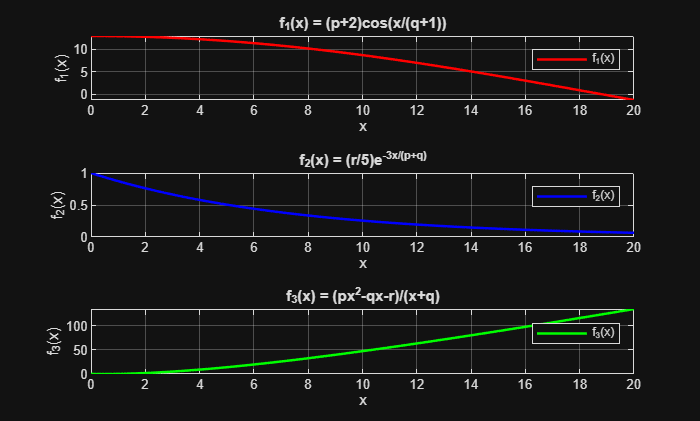


figure
tiledlayout(3,1)

nexttile
plot(x, f1, 'r-', 'LineWidth', 1.5)
title('f_1(x) = (p+2)cos(x/(q+1))')
xlabel('x')
ylabel('f_1(x)')
grid on
legend('f_1(x)')

nexttile
plot(x, f2, 'b-', 'LineWidth', 1.5)
title('f_2(x) = (r/5)e^{-3x/(p+q)}')
xlabel('x')
ylabel('f_2(x)')
grid on
legend('f_2(x)')

nexttile
plot(x, f3, 'g-', 'LineWidth', 1.5)
title('f_3(x) = (px^2-qx-r)/(x+q)')
xlabel('x')
ylabel('f_3(x)')
grid on
legend('f_3(x)')

**3.2**

f0 = d(9)

f0 =      1



t1 = 0:0.005:1

t1 =                    0   0.005000000000000   0.010000000000000   0.015000000000000   0.020000000000000   0.025000000000000   0.030000000000000   0.035000000000000   0.040000000000000   0.045000000000000   0.050000000000000   0.055000000000000   0.060000000000000   0.065000000000000   0.070000000000000   0.075000000000000   0.080000000000000   0.085000000000000   0.090000000000000   0.095000000000000   0.100000000000000   0.105000000000000   0.110000000000000   0.115000000000000   0.120000000000000   0.125000000000000   0.130000000000000   0.135000000000000   0.140000000000000   0.145000000000000   0.150000000000000   0.155000000000000   0.160000000000000   0.165000000000000   0.170000000000000   0.175000000000000   0.180000000000000   0.185000000000000   0.190000000000000   0.195000000000000   0.200000000000000   0.205000000000000   0.210000000000000   0.215000000000000   0.220000000000000   0.225000000000000   0.230000000000000   0.235000000000000   0.240000000000000   0.2450000000

s1 = sin(2*pi*f0*t1) + 0.35*sin(8*pi*f0*t1)

s1 =                    0   0.075277390825635   0.149831980037013   0.222951906758152   0.293947019499905   0.362159303342596   0.426972801660766   0.487822876368069   0.544204661090560   0.595680574402336   0.641886775078251   0.682538458000332   0.717433907634573   0.746457245584676   0.769579829320114   0.786860280442851   0.798443142464822   0.804556189676077   0.805506429950523   0.801674864927172   0.793510090594839   0.781520839588577   0.766267583188327   0.748353325831351   0.728413737676195   0.707106781186547   0.685101995673905   0.663069609122760   0.641669649336152   0.621541226440090   0.603292156072582   0.587489087199521   0.574648290530489   0.565227253078238   0.559617211680757   0.558136743485064   0.561026514710979   0.568445270734086   0.580467130938356   0.597080231199184   0.618186735591850   0.643604217313836   0.673068387202926   0.706237126967221   0.742695763653648   0.781963502292772   0.823500915378877   0.866718371163443   0.910985267920572   0.9556399286

t2 = 0:0.03:1 

t2 =                    0   0.030000000000000   0.060000000000000   0.090000000000000   0.120000000000000   0.150000000000000   0.180000000000000   0.210000000000000   0.240000000000000   0.270000000000000   0.300000000000000   0.330000000000000   0.360000000000000   0.390000000000000   0.420000000000000   0.450000000000000   0.480000000000000   0.510000000000000   0.540000000000000   0.570000000000000   0.600000000000000   0.630000000000000   0.660000000000000   0.690000000000000   0.720000000000000   0.750000000000000   0.780000000000000   0.810000000000000   0.840000000000000   0.870000000000000   0.900000000000000   0.930000000000000   0.960000000000000   0.990000000000000


s2 = sin(2*pi*f0*t2) + 0.35*sin(8*pi*f0*t2)

s2 =                    0   0.426972801660766   0.717433907634573   0.805506429950523   0.728413737676195   0.603292156072582   0.561026514710979   0.673068387202926   0.910985267920572   1.160728487250078   1.283926296998457   1.192996148406971   0.899356836215427   0.508580396309053   0.165064205738609  -0.023852786328356  -0.043280552371296   0.024250940978386   0.046824886760850  -0.081978753810032  -0.382060413990107  -0.772835259168917  -1.114007560473542  -1.279085840838146  -1.221878737803730  -1.000000000000000  -0.742695763653648  -0.580467130938356  -0.574648290530489  -0.685101995673905  -0.793510090594839  -0.769579829320114  -0.544204661090561  -0.149831980037012


t3 = 0:0.10:1 

t3 =                    0   0.100000000000000   0.200000000000000   0.300000000000000   0.400000000000000   0.500000000000000   0.600000000000000   0.700000000000000   0.800000000000000   0.900000000000000   1.000000000000000


s3 = sin(2*pi*f0*t3) + 0.35*sin(8*pi*f0*t3)

s3 =                    0   0.793510090594839   0.618186735591850   1.283926296998457   0.382060413990108  -0.000000000000000  -0.382060413990107  -1.283926296998457  -0.618186735591850  -0.793510090594839  -0.000000000000001



referencia_t = 0:0.001:1

referencia_t =                    0   0.001000000000000   0.002000000000000   0.003000000000000   0.004000000000000   0.005000000000000   0.006000000000000   0.007000000000000   0.008000000000000   0.009000000000000   0.010000000000000   0.011000000000000   0.012000000000000   0.013000000000000   0.014000000000000   0.015000000000000   0.016000000000000   0.017000000000000   0.018000000000000   0.019000000000000   0.020000000000000   0.021000000000000   0.022000000000000   0.023000000000000   0.024000000000000   0.025000000000000   0.026000000000000   0.027000000000000   0.028000000000000   0.029000000000000   0.030000000000000   0.031000000000000   0.032000000000000   0.033000000000000   0.034000000000000   0.035000000000000   0.036000000000000   0.037000000000000   0.038000000000000   0.039000000000000   0.040000000000000   0.041000000000000   0.042000000000000   0.043000000000000   0.044000000000000   0.045000000000000   0.046000000000000   0.047000000000000   0.048000000000000   0.

referencia_s = sin(2*pi*f0*referencia_t) + 0.35*sin(8*pi*f0*referencia_t)

referencia_s =                    0   0.015078677370727   0.030151551246272   0.045212821650185   0.060256695641263   0.075277390825635   0.090269138862200   0.105226188959212   0.120142811359812   0.135013300814308   0.149831980037013   0.164593203145470   0.179291359079895   0.193920875000681   0.208476219661824   0.222951906758152   0.237342498244236   0.251642607622909   0.265846903201308   0.279950111312390   0.293947019499905   0.307832479664799   0.321601411171092   0.335248803909246   0.348769721315122   0.362159303342596   0.375412769387996   0.388525421164479   0.401492645524582   0.414309917229125   0.426972801660766   0.439476957480457   0.451818139225174   0.463992199845242   0.475995093179691   0.487822876368069   0.499471712197198   0.510937871381397   0.522217734774739   0.533307795513942   0.544204661090560   0.554905055351161   0.565405820424231   0.575703918572609   0.585796433970267   0.595680574402336   0.605353672887297   0.614813189220332   0.624056711436849   0.

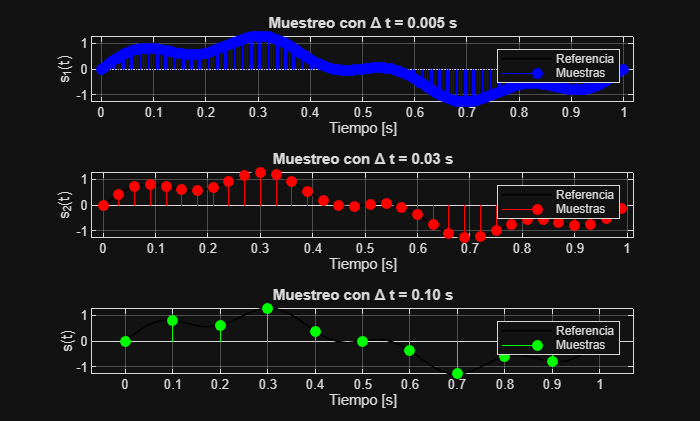

figure
tiledlayout(3,1)
nexttile
plot(referencia_t, referencia_s, 'k-', 'LineWidth', 1)
hold on
stem(t1,s1,'b','filled')
hold off
title('Muestreo con \Delta t = 0.005 s')
xlabel('Tiempo [s]')
ylabel('s_1(t)')
grid on
legend('Referencia', 'Muestras')

nexttile
plot(referencia_t, referencia_s, 'k-', 'LineWidth', 1)
hold on
stem(t2,s2,'r','filled')
hold off
title('Muestreo con \Delta t = 0.03 s')
xlabel('Tiempo [s]')
ylabel('s_2(t)')
grid on
legend('Referencia', 'Muestras')

nexttile
plot(referencia_t, referencia_s, 'k-', 'LineWidth', 1)
hold on
stem(t3, s3,'g', 'filled')
hold off
title('Muestreo con \Delta t = 0.10 s')
xlabel('Tiempo [s]')
ylabel('s(t)')
grid on
legend('Referencia', 'Muestras')

## **Punto 4**

**4.1**

M = [ -7   9   35   -3   16   12;
      15   5   15   98   54   -6;
      18  -1   13   57   -2   55;
      22   0   41   33   87   81;
      36   7   -4   15   69  -34;
      -9  65   70   -8   5   25 ];


**a.**

B = M(3,6)

B =     55


C = M(:,5)

C =     16
    54
    -2
    87
    69
     5


D = M(2:5,3:6) 

D =     15    98    54    -6
    13    57    -2    55
    41    33    87    81
    -4    15    69   -34


## **Indexación:**

La utilización de la indexación por filas/columnas o indexación lineal son equivalentes en términos prácticos, pues ambas cumplen con la misma utilidad de acceder a trozos de la información de un vector o matriz, sin embargo, es importante contemplar que utilizan diferentes referencias para lo que podrian ser los mismos puntos de información de un arreglo. Mientras que la indexación por filas/columnas utiliza, como indica su nombre, las ubicaciones espaciales de una matriz que es naturalmente bidimensional, es decir, si tenemos un arreglo $A \in R^{2x2}$, podemos acceder a sus componentes $A_{i,j}$ utilizado la indexación A(i,j) donde *i *hace referencia a las filas y *j *a las columnas y $i,j \in \{1,2\}$. En cuanto a la indexación lineal, la matrix se indexa como si fuera un vector $a \in \mathbb{R}$ que, informalmente, anexa cada fila al ultimo elemento de la anterior para formar una suerte de vector unidimensional a la hora de acceder a sus elementos. Nuevamente, si tenemos una matrix $A \in R^{2x2}$, con indexación lineal podemos pensarla como $a \in \mathbb{R}$  y acceder al elemento $A_{i,j}$ donde  $i,j \in \{1,2\}$ se traduce a $A_k $ utilizando la indexación A(k) donde $k = i + (j-1)m,$ siendo *m *es el total de filas cumpliendo $A(i,j) = A\big(i + (j-1)m\big).
$

**b.**

E = diag(M)

E =     -7
     5
    13
    33
    69
    25


F = M(triu(true(size(M)), 1))

F =      9
    35
    15
    -3
    98
    57
    16
    54
    -2
    87
    12
    -6
    55
    81
   -34


Contemplado que $M \in \mathbb{R}^{6x6}$ podemos hacer una prueba a fuerza bruta de la cantidad de elementos en **F**. Retirar la diagonal principal y la sección triangular inferior de la misma, supone eliminar una cantidad $\zeta = \sum_{x=1}^{i} x $ de la matriz, donde $i = 6$ es la cantidad de filas/columnas, pues de cada fila se retira una cantidad de elementos equivalente al número de fila, la sumatoria resulta en $\zeta = 21$ por lo que $|F| = 6 \cdot 6 - \zeta = 15$, equivalente a la cantidad de elementos en **F.** 

**c.**

negativos = M(M<0);
[fila_neg, columna_neg] = find(M < 0);
disp('Valores negativos de M'); disp(negativos')

Valores negativos de M
    -7    -9    -1    -4    -3    -8    -2    -6   -34



disp('Posiciones de negativos:'); disp([fila_neg columna_neg])

Posiciones de negativos:
     1     1
     6     1
     3     2
     5     3
     1     4
     6     4
     3     5
     2     6
     5     6



media = mean(M(:));
fprintf('Media de M: %.4f\n', media);

Media de M: 24.5556


mayores_media = M(M > media);
[fila_mayor_media, columna_mayor_media] = find(M > media); 
disp('Valores mayores que la media:'); disp(mayores_media')

Valores mayores que la media:
    36    65    35    41    70    98    57    33    54    87    69    55    81    25



disp('Posiciones de mayores que la media:'); disp([fila_mayor_media columna_mayor_media])

Posiciones de mayores que la media:
     5     1
     6     2
     1     3
     4     3
     6     3
     2     4
     3     4
     4     4
     2     5
     4     5
     5     5
     3     6
     4     6
     6     6



[valores,indices] = sort(abs(M(:)),'descend');
top3_valores = M(indices(1:3));
top3_posiciones = indices(1:3); 
[top3_fila, top3_columna] = ind2sub(size(M), top3_posiciones);
disp('Top 3 valores de mayor magnitud absoluta:'); disp(top3_valores')

Top 3 valores de mayor magnitud absoluta:
    98    87    81



disp('En posiciones:'); disp([top3_fila top3_columna]);

En posiciones:
     2     4
     4     5
     4     6



**d.**

mu = mean(M,1);
sigma = std(M,0,1);
Z = (M - mu)./sigma;
media_Z = mean(Z,1);
sigma_Z = std(Z,0,1);
disp('Z (matriz normalizada) ='); disp(Z)

Z (matriz normalizada) =
  -1.117850267774412  -0.204973742220589   0.255680064184295  -0.869796782408251  -0.601483692061360  -0.245156730681972
   0.143314136894155  -0.363663091036529  -0.511360128368590   1.640188218255560   0.429631208615257  -0.679204712873004
   0.315291101167142  -0.601697114260439  -0.588064147623879   0.621283416005894  -1.089906539750283   0.791735671218827
   0.544593720197791  -0.562024777056454   0.485792121950161   0.024851336640236   1.325073096044951   1.418693867716985
   1.347152886805061  -0.284318416628559  -1.240048311293831  -0.422472722884008   0.836650248356027  -1.354390462947944
  -1.232501577289737   2.016677141202571   1.598000401151844  -0.994053465609430  -0.899964321204591   0.068322367567107



disp('Media de cada columna de Z:'); disp(media_Z)

Media de cada columna de Z:
   1.0e-15 *

  -0.037007434154172   0.074014868308344   0.111022302462516  -0.018503717077086   0.055511151231258  -0.083266726846887



disp('Desv. estándar de cada columna de Z:'); disp(sigma_Z)

Desv. estándar de cada columna de Z:
   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000



La normalización prueba ser efectiva para alinear cada columna muy cerca de una media 0 y con una desviación estandar de 1 como es esperado de las formulas. Este resultado es supremamente útil al utilizar variables con coeficientes asociados de diferentes ordenes de magnitud, para problemas de inversión u optimización como podría ser mínimos cuadrados o cualquier otra aproximación para la invers de una matriz, una normalización de este tipo permite eliminar sesgos del problema, pues todas las variables tienen el mismo peso (1) en sus coeficientes.

**e.**

sub1 = [M(3,1) M(4,3); M(1,4) M(5,1)]

sub1 =     18    41
    -3    36


sub2 = [M(2,3) M(2,5); M(6,3) M(1,5)]

sub2 =     15    54
    70    16


sub3 = [M(1,1) M(6,6); M(2,2) M(3,3)]

sub3 =     -7    25
     5    13


sub_transpuesta = sub3'

sub_transpuesta =     -7     5
    25    13


fprintf('Dimensiones: sub1=%dx%d, sub2=%dx%d, sub3''=%dx%d\n',size(sub1,1), size(sub1,2), size(sub2,1), size(sub2,2), ...
    size(sub3',1), size(sub3',2));

Dimensiones: sub1=2x2, sub2=2x2, sub3'=2x2


G = sub1 * sub2 + sub3'

G =         3133        1633
        2500         427


verificacion_G11 = sub1(1,1)*sub2(1,1) + sub1(1,2)*sub2(2,1) + sub3(1,1);
fprintf('Verificación manual G(1,1) = %d | MATLAB: G(1,1) = %d\n', verificacion_G11, G(1,1));

Verificación manual G(1,1) = 3133 | MATLAB: G(1,1) = 3133


**4.2**

**Funciones auxiliares: **

El algoritmo se separa en cuatro tareas: localizar letras iniciales candidatas, identificar direcciones posibles, validar los límites de la matriz y verificar letra por letra si una palabra está presente en una dirección determinada.

%Busca desde una posición inicial, la siguiente celda
%de la sopa de letras que pueda ser el comienzo de al menos una palabra

function [fila_salida,columna_salida, palabras_a_buscar] = continuar_recorrido(fila_entrada, columna_entrada, S, palabras)
    salto_linea = false;
    encontrado = false;
    i = fila_entrada;
    % Recorre las filas desde la fila inicial hasta el final de la matriz.
    while i <= length(S) && ~encontrado
        if ~salto_linea
            j = columna_entrada;
        else
            j = 1;
        end
        % Recorre las columnas de la fila actual.
        while j <= length(S(i,:)) && ~encontrado
            letra_actual = S(i,j);
            palabras_a_buscar = {};
            % Identifica cuáles palabras pueden iniciar con letra_actual.
            for indice_palabra = 1:numel(palabras)
                if palabras{indice_palabra}(1) == letra_actual
                    palabras_a_buscar{end+1}=palabras{indice_palabra};
                    encontrado = true;
                    fila_salida = i;
                    columna_salida = j;
                end
            end
            j=j+1;
        end
        salto_linea = true;
        i=i+1;
    end
end

% Comprueba si alguna de las palabras candidatas está
% presente en la sopa de letras, partiendo de una posición y siguiendo
% las direcciones indicadas.

function palabras_encontradas =  verificar_palabra(fila_entrada, columna_entrada, direcciones, S, palabras, palabras_a_anexar)
    n = 2;
    fallo = false;
    i = 1;
    no_hay_direcciones = false;
    
    % Punto inicial
    fila_inicio=fila_entrada;
    columna_inicio=columna_entrada;
    % Evalúa cada una de las direcciones candidatas.  
    while i <= length(direcciones(:,1)) && ~no_hay_direcciones
        fila_entrada = fila_inicio;
        columna_entrada = columna_inicio;
        n=2;
        fallo = false;
        % Dirección de desplazamiento
        delta_i = direcciones(i, 1);
        delta_j = direcciones(i, 2);
        if ~(delta_i ==0 && delta_j==0)
        indice_palabras = 1;
        % Verifica cada palabra que puede empezar en la celda inicial
        while indice_palabras <= numel(palabras)
            fallo = false;
            fila_entrada = fila_inicio;
            columna_entrada = columna_inicio;
            n=2;
            "EMPIEZA ANALISIS PALABRA: " + palabras{indice_palabras} + ", Dir: (" + delta_i+","+delta_j+")";
            % Evita analizar una palabra ya encontrada.
            encontrar = contains(palabras_a_anexar, palabras{indice_palabras}, 'IgnoreCase', true); 
            if sum(encontrar) > 0
                "YA SE ENCONTRO";
                fallo = true;
            end
            % Compara las letras restantes siguiendo la dirección actual
            while n <= length(palabras{indice_palabras}) && ~fallo
                if mirar_validez(fila_entrada+delta_i, columna_entrada+delta_j, S)
                    if S(fila_entrada+delta_i, columna_entrada+delta_j) == palabras{indice_palabras}(n)
         
                        n=n+1;
                        fila_entrada = fila_entrada+delta_i;
                        columna_entrada = columna_entrada+delta_j;
                        palabras{indice_palabras}(n-1) +", " + S(fila_entrada, columna_entrada);
                        
                    else
                        fallo = true;
                        x = fila_entrada+delta_i;
                        y=columna_entrada+delta_j;
                        "FALLO, Palabra: " + palabras{indice_palabras} + ", Pos: " +  x + "," + y;
                        palabras{indice_palabras}(n) +", " + S(x, y);
                    end
                else
                    "FALLO EN VALIDEZ";
                    fallo = true;
                end
            end
            % Si se verificaron todas las letras, se registra la palabra.
            if ~fallo
                "ENCONTRADA";
                palabras{indice_palabras};
                palabras_a_anexar = [palabras_a_anexar, palabras{indice_palabras} + ", Inicio: " + fila_inicio+","+columna_inicio+", Final: "+fila_entrada+","+columna_entrada+", Dir:" + delta_i+","+delta_j];

                
            end
            indice_palabras = indice_palabras+1;
        end
        else
        no_hay_direcciones = true;
        end
        i=i+1;

    end
    palabras_encontradas=palabras_a_anexar;
end


% Verifica si una posición pertenece a los límites de la matriz de la sopa de letras
% La posición es válida si sus índices son positivos y no superan las dimensiones de la matriz.
function [valido] = mirar_validez(fila_entrada,columna_entrada, S)
        if fila_entrada>0 && fila_entrada<length(S) && columna_entrada>0 && columna_entrada<length(S(fila_entrada,:))
            valido=true;
        else
            valido=false;
        end
end


% Identifica las direcciones desde una posición inicial hacia
% las celdas vecinas que contienen la segunda letra de alguna posible   palabra.

function posibles_direcciones = mirar_vecinos(fila_entrada,columna_entrada, palabras, radio, S)
    posibles_direcciones = zeros(0,2);
    
    %Recorrido de filas y columnas
    i = fila_entrada-radio;
    while i <= fila_entrada+radio
        j = columna_entrada-radio;
        while j <= columna_entrada+radio
            if mirar_validez(i,j, S) && (i ~= fila_entrada || j ~= columna_entrada)
                 % Compara la letra vecina con la segunda letra de cada palabra
                for indice_palabras=1:numel(palabras)
                    %Si coincide se almacena el desplazamiento
                    if S(i,j) == palabras{indice_palabras}(2)
                        posibles_direcciones(end+1,:)=[i-fila_entrada, j-columna_entrada];
                    end
                    
                end
                j=j+1;
            else
                j = j+1;
            end
        
        end

    
        i=i+1;
    end

end

**Solución**

load('sopa_de_letras.mat');
palabras

palabras = 1×7 cell array
    {'INDEXACION'}    {'MATRIZ'}    {'MATLAB'}    {'COMPUTACION'}    {'CIENTIFICA'}    {'ECUACION'}    {'PUNTOFLOTANTE'}


palabras_encontradas={};

i = 1;

fila_inicial=1;
columna_inicial=1;
S

S = 24×24 char array
    'DLZOOYOXISUKLJIAXZBDUHCF'
    'WCINDEXACIONATIGSWGEJPAB'
    'TTQQFJCYXQTOGCBPIHCXXIVS'
    'VIFGKQKYTNTTIGAAFIRVSNZY'
    'ETYXNFJCEVRENIWKSFXMDMXO'
    'DCPHIUVAQPNEIFMRCYDAEISK'
    'ICUIFQZNGTILUKIDHLTTOOQT'
    'ZYRHDJXKIWXJHMBQCSPREPWU'
    'PUEKOBZFULIZJZDIYGMIRKRS'
    'GHDLSLINPNWHZQDZNKSZLWVB'
    'YOAOSCBODJNKVNFNHRPVJKDT'
    'EJKTAINSDODQBKGYWLWCNJLE'
    'TKITLZQXIMVYPWQBJLOZXTBX'
    'NRMSLJDCINCSOLSKSISHBZIE'
    'ATYAVHAQSALJFZZQRXXQZZVO'
    'TRASTUMLPNEJHWOSBTKYVOMP'
    'OTFGCLGSJYCMRQYEHIZRDYKP'
    'LBYEELALONPMRXKSGPPFXIJS'
    'FCAKYLFBPZZDIQOEQGIPDJXU'
    'OAWOAXFDDVPQBWKSTGBSUQPU'
    'TKYXNCZTROWDASHTYNDFKYKU'
    'NBHVFYBBPLPNOICATUPMOCSY'
    'UIJFBKYDMZSVYMLZPXOZLECD'
    'PUEFHGZOXUZGPKHTXISWXLUM'


finalizo = false;
while length(palabras_encontradas) ~= length(palabras) && ~finalizo
    [fila_inicial, columna_inicial, palabras_a_mirar] = continuar_recorrido(fila_inicial, columna_inicial, S, palabras);
    posibles_direcciones = mirar_vecinos(fila_inicial, columna_inicial, palabras_a_mirar, 1, S);
    palabras_encontradas=verificar_palabra(fila_inicial, columna_inicial, posibles_direcciones, S, palabras_a_mirar, palabras_encontradas);
    if columna_inicial < length(S(1,:))
        columna_inicial=columna_inicial+1;
    else
        if fila_inicial < length(S(:,1))

            columna_inicial=1;
            fila_inicial = fila_inicial+1;
        else
            finalizo = true;
        end
    end
end
palabras_encontradas

palabras_encontradas = 1×7 string array
    "INDEXACION, Inicio: 2,3, Final: 2,12, Dir:0,1"    "CIENTIFICA, Inicio: 3,14, Final: 12,5, Dir:1,-1"    "MATRIZ, Inicio: 5,20, Final: 10,20, Dir:1,0"    "MATLAB, Inicio: 14,3, Final: 19,8, Dir:1,1"    "ECUACION, Inicio: 18,4, Final: 11,11, Dir:-1,1"    "COMPUTACION, Inicio: 22,22, Final: 22,12, Dir:0,-1"    "PUNTOFLOTANTE, Inicio: 24,1, Final: 12,1, Dir:-1,0"


INDEXACION: [2,3] -> [2,12]
CIENTIFICA: [3,14] -> [12,5]
MATRIZ: [5,20] -> [10,20]
MATLAB: [14,3] -> [19,8]
ECUACION: [18,4] -> [11,11]
COMPUTACION: [22,22] -> [22,12]
PUNTOFLOTANTE: [24,1] -> [12,1]


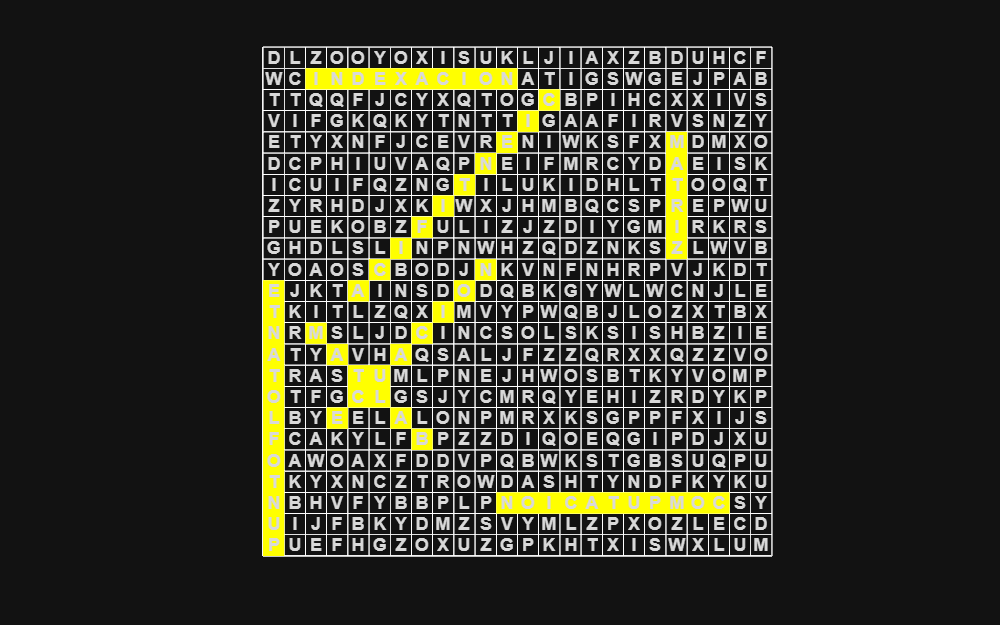


function visualizeSoup(sopa, data)

[rows, cols] = size(sopa);

figure('Position',[100 100 800 500])
hold on

% Grid
for x = 0.5:1:cols+0.5
    plot([x x], [0.5 rows+0.5], 'w');
end

for y = 0.5:1:rows+0.5
    plot([0.5 cols+0.5], [y y], 'w');
end


% Pintar las celdas

for k = 1:length(data)

    tokens = regexp(data{k}, ...
        '(\w+), Inicio: (-?\d+),(-?\d+), Final: (-?\d+),(-?\d+), Dir:(-?\d+),(-?\d+)', ...
        'tokens');

    tokens = tokens{1};

    word  = tokens{1};

    start = [str2double(tokens{2}), str2double(tokens{3})];
    final = [str2double(tokens{4}), str2double(tokens{5})];
    dir   = [str2double(tokens{6}), str2double(tokens{7})];

    fprintf('%s: [%d,%d] -> [%d,%d]\n', ...
        word, start, final);

    pos = start;

    while true

        row = pos(1);
        col = pos(2);

        rectangle( ...
            'Position', [col-0.5, row-0.5, 1, 1], ...
            'FaceColor', 'yellow', ...
            'EdgeColor', 'none');

        if isequal(pos, final)
            break
        end

        pos = pos + dir;

    end

end

% Letras
for i = 1:rows
    for j = 1:cols
        text(j, i, sopa(i,j), ...
            'HorizontalAlignment', 'center', ...
            'VerticalAlignment', 'middle', ...
            'FontSize', 11, ...
            'FontWeight', 'bold');
    end
end


axis equal
xlim([0.5 cols+0.5])
ylim([0.5 rows+0.5])

set(gca, 'YDir', 'reverse')
set(gca, 'XTick', [])
set(gca, 'YTick', [])

hold off

end
visualizeSoup(S,palabras_encontradas);

## Análisis:

**Verificación de límites**

La función auxiliar *mirar_validez* es la encargada de revisar los límites de la matriz. Recibe una fila y columna candidatas y devuelve *true* únicamente si ambas estan en el rango válido de la matriz, es decir, dentro de las dimensiones de la misma. Esto garantiza que al intentar evaluar, por ejemplo, `S(0,j)` o `S(i,columnas+1)`, no se produzca un erro de indexacion.

**Búsquedas horizontales, verticales y diagonales**

El tipo de busqueda se define en la función auxiliar *mirar_vecinos* que depende de los desplazamientos `delta_i` y `delta_j`, obtenidos de la matriz *direcciones. *Los desplazamientos se generan dinámicamente comparando la posición inicial con los vecinos que son letras que coinciden la siguiente de alguna palabra no encontrada.

- En una búsqueda **horizontal**, la fila no cambia $\Delta i= 0$  y solo cambia la columna.  (0,1) busca hacia la derecha, mientras que (0,−1) busca hacia la izquierda.

- En una búsqueda **vertical**, la columna no cambia $\Delta j = 0$ y solo cambia la fila. (1,0) busca hacia arriba y (−1,0) hacia abajo.

- En una búsqueda **diagonal**, cambian simultáneamente la fila y la columna. (1,1) es una busqueda en la diagonal superior derecha y (−1,−1), busca en una diagonal inferior izquierda.

**Letras repetidas y candidatos**

Dado que el algoritmo no logra discernir realmente cual aparición de una letra pertenece a una palabra buscada, las letras repetidas producen varios candidatos. La función auxiliar *continuar_recorrido *recorre la sopa, al encontrar una letra que coincide con la primera letra de al menos una de las palabras buscadas, guarda todas las palabras formadas desde esa letra.

La funcion auxiliar *mirar_vecinos, *como indica su nombre, revisa las posiciones contiguas, si los vecinos contienen la segunda letra de una posible palabra, se genera una direcciones de busqueda. 

Finalmente, la función auxiliar *verificar_palabra *evalúa las combinaciones encontradas y las direcciones letra a latra. Si las letras coinciden consecutivamente con una de las palabras buscadas, se acepta la candidata, de lo contrario se descarta.

## Conclusiones

## **Referencias**

[1] The MathWorks, Inc., “Create Live Scripts in the Live Editor”, documentación oficial de MATLAB. 

[2] The MathWorks, Inc., “Array Indexing”, documentación oficial de MATLAB. 

[3] The MathWorks, Inc., documentación de plot, stem, tiledlayout, fill, load y reshape